# L5 -  Exercici 3

Activitat d'evaluació continuada 

Calcular aproximacions del nombre $\pi$ fent ús de la fórmula

## 
$$\pi=\displaystyle\int_{0}^{1}\frac{4}{1+t^2}\,dt\, \quad\quad\quad
\left(\arctan(x)=\displaystyle\int_{0}^{x}\frac{1}{1+t^2}\,dt\,,\quad x>0\,\right).$$


format short g
f = @(x)4./(x.^2+1);
ve = integral(f,0,1);

**a)** Useu la regla composta de Trapezis, preneu $\(h=\displaystyle\frac{1}{2k},\ k=4,16,\,64\)$ . És l'error proporcional a $\( h^p \)
$? Per què? Presenteu els resultats en taules.

format short g
% Trapezis per h=1/(2*k) i k=4,16,64
trtab = zeros(3,4);
w = zeros(1,2^5);
k = [4,16,64];
for i = 1:3
    h = 1/(2*k(i));
    x = 0:h:1;
    y = f(x);
    w = [1 2*ones(1,length(y)-2) 1];
    va = sum(y.*w*(h/2));
    trtab(i,:)=[i h va abs(va-ve)];
end
trapsTable = splitvars(table(trtab));
trapsTable.Properties.VariableNames ={'k' 'h' 'va_pi','errAbs'};
disp(trapsTable)

    k        h        va_pi       errAbs  
    _    _________    ______    __________

    1        0.125     3.139     0.0026042
    2      0.03125    3.1414    0.00016276
    3    0.0078125    3.1416    1.0173e-05



**b)** Useu la regla composta de Simpson, preneu  i  $\(h=\displaystyle\frac{1}{2k},\ k=4,16,\,64\)$. És l'error proporcional a \( h^p \)? Per què? Presenteu els resultats en taules.

format short g
sitab = zeros(3,4);
w = zeros(1,2^5);
k = [4,16,64];
for i = 1:3
    h = 1/(2*k(i));
    x = 0:h:1;
    y = f(x);
    w = 4*ones(1,length(y)-2);
    w(2:2:end) = 2;
    w = [1 w 1] ;
    va = sum(y.*w*(h/3));
    sitab(i,:)=[i h va abs(va-ve)];
end
simpsTable = splitvars(table(sitab));
simpsTable.Properties.VariableNames ={'k' 'h' 'va_pi' 'errAbs'};
disp(simpsTable)

    k        h        va_pi       errAbs  
    _    _________    ______    __________

    1        0.125    3.1416    1.5113e-07
    2      0.03125    3.1416    3.6957e-11
    3    0.0078125    3.1416    9.3259e-15



**c)** Apliqueu el métode de Romberg, comenceu amb $\(h=\displaystyle\frac{1}{2^k},\ k=0,1,2,3,4,\dots\)$  per millorar l’aproximació de $\(\pi \)$ obtinguda en els apartats anteriors fins obtenir 14 xifres decimals correctes. Presenteu els resultats en taules.

format short g
% Trapezis per h=2^(-k) i k=0,1,2,3,4,5
trtab = zeros(6,4);
w = zeros(1,2^5);
for i = 0:5
    h = 2^(-i);
    x = 0:h:1;
    y = f(x);
    w = [1 2*ones(1,length(y)-2) 1];
    va = sum(y.*w*(h/2));
    trtab(i+1,:)=[i h va abs(va-ve)];
end
trapsTable = splitvars(table(trtab));
trapsTable.Properties.VariableNames ={'k' 'h' 'va_pi','errAbs'};
disp(trapsTable)

    k       h        va_pi       errAbs  
    _    _______    _______    __________

    0          1    0.77174      0.070957
    1        0.5    0.82526      0.017438
    2       0.25    0.83837      0.004333
    3      0.125    0.84162     0.0010816
    4     0.0625    0.84243    0.00027029
    5    0.03125    0.84263    6.7565e-05



% Romberg 
format short g
n=length(trtab(:,3));
R=zeros(n,n-2); ERabs=zeros(n,n-2); ERrel=zeros(n,n-2); XC=zeros(n,n-2); 
R(:,1) = trtab(:,3); 
ERabs(:,1) = trtab(:,4);
ERrel(:,1) = trtab(:,4)/abs(ve);
XC(:,1) = fix(-log10(2*ERrel(:,1)));
for k=2:n-2
    for i=n:-1:k
        R(i,k)=R(i,k-1)+((R(i,k-1)-R(i-1,k-1))/(4^(k-1)-1));
        ERabs(i,k) = abs(R(i,k)-ve);
        ERrel(i,k) = ERabs(i,k)/abs(ve);
        XC(i,k) = fix(-log10(2*ERrel(i,k)));
    end
end

rtab = [(0:n-1)',1./2.^(0:n-1)',R];
romTable = splitvars(table(rtab));
romTable.Properties.VariableNames ={'k' 'h' 'R_1' 'R_2' 'R_3' 'R_4'};
disp(romTable)

    k       h         R_1        R_2        R_3       R_4  
    _    _______    _______    _______    _______    ______

    0          1    0.77174          0          0         0
    1        0.5    0.82526     0.8431          0         0
    2       0.25    0.83837    0.84274    0.84271         0
    3      0.125    0.84162     0.8427     0.8427    0.8427
    4     0.0625    0.84243     0.8427     0.8427    0.8427
    5    0.03125    0.84263     0.8427     0.8427    0.8427



rombTable = splitvars(table([(0:n-1)',1./2.^(0:n-1)',ERabs]));
rombTable.Properties.VariableNames = {'k' 'h' 'ER_1' 'ER_2' 'ER_3' 'ER_4'};
fprintf('\n%12s\n\n', 'Error absolut Romberg'); disp(rombTable)

Error absolut Romberg

    k       h          ER_1          ER_2          ER_3          ER_4   
    _    _______    __________    __________    __________    __________

    0          1      0.070957             0             0             0
    1        0.5      0.017438    0.00040204             0             0
    2       0.25      0.004333    3.5258e-05    1.0807e-05             0
    3      0.125     0.0010816    2.2429e-06     4.186e-08    1.2901e-07
    4     0.0625    0.00027029    1.4062e-07    4.7075e-10    1.8623e-10
    5    0.03125    6.7565e-05    8.7952e-09    6.7421e-12    6.2306e-13



**d)** Useu una tècnica de simulació (Mètode de MonteCarlo) per a determinar $\(\pi \)$ preneu mostres de mida $\(10^{n},\ n\geq 3,4,5,6,\dots\)$. Presenteu els resultats que s’obtenen en taules.

%  Simulació Montecarlo
mctab = montecarlo(f,7);
monteTable = splitvars(table(mctab));
monteTable.Properties.VariableNames ={'k' 'M' 'va_pi' 'errAbs'};
format long g
disp(monteTable)

    k       M             va_pi                 errAbs       
    _    ________    ________________    ____________________

    3        1000    3.14890741572068     0.00731476213088245
    4       10000    3.13200695735268     0.00958569623711059
    5      100000    3.14158063794677    1.20156430249985e-05
    6     1000000    3.14061963000833    0.000973023581464449
    7    10000000    3.14204316060399    0.000450507014197132



**e**) Useu $\(\pi\)$ de Matlab®, calculeu l’error absolut i l’error relatiu de les aproximació dels apartats (a), (b),(c)  i (d). Quantes xifres significatives correctes s’han obtingut? Explica els teus càlculs.  Com s’ha de pendre la mostra de gran en el mètode de MonteCarlo per obtenir la mateixa exactitud que amb la fórmula dels trapezis? Podem obtenir la mateixa exactitud que amb la fórmula de Simpson? Argumenta la teva resposta

format short g
trapsTable = splitvars(table([trtab(:,1) trtab(:,4) trtab(:,4)/abs(ve) fix(-log10(2*trtab(:,4)))]));

trapsTable.Properties.VariableNames ={'k' 'errAbs' 'errRel' 'xifres'};
fprintf('\n%12s\n\n', 'Error Trapezis');disp(trapsTable)


Error Trapezis

    k      errAbs        errRel      xifres
    _    __________    __________    ______

    0       0.14159       0.04507      0   
    1      0.041593      0.013239      1   
    2      0.010416     0.0033156      1   
    3     0.0026042    0.00082893      2   
    4    0.00065104    0.00020723      2   
    5    0.00016276    5.1808e-05      3   




fprintf('\n%12s\n\n', 'Error absolut Romberg'); disp(rombTable)


Error absolut Romberg

    k       h          ER_1          ER_2          ER_3          ER_4   
    _    _______    __________    __________    __________    __________

    0          1       0.14159             0             0             0
    1        0.5      0.041593     0.0082593             0             0
    2       0.25      0.010416    2.4026e-05    0.00052499             0
    3      0.125     0.0026042    1.5113e-07    1.4405e-06    6.8698e-06
    4     0.0625    0.00065104     2.365e-09    7.5528e-09    1.5193e-08
    5    0.03125    0.00016276    3.6956e-11    1.1824e-10     2.367e-13



rombgTable = splitvars(table([(0:n-1)',1./2.^(0:n-1)',ERrel]));
rombgTable.Properties.VariableNames = {'k' 'h' 'ER_1' 'ER_2' 'ER_3' 'ER_4'};
fprintf('\n%12s\n\n', 'Error relatiu Romberg'); disp(rombgTable)


Error relatiu Romberg

    k       h          ER_1          ER_2          ER_3          ER_4   
    _    _______    __________    __________    __________    __________

    0          1       0.04507             0             0             0
    1        0.5      0.013239      0.002629             0             0
    2       0.25     0.0033156    7.6478e-06    0.00016711             0
    3      0.125    0.00082893    4.8107e-08    4.5854e-07    2.1867e-06
    4     0.0625    0.00020723    7.5279e-10    2.4041e-09    4.8361e-09
    5    0.03125    5.1808e-05    1.1764e-11    3.7639e-11    7.5344e-14




rombdcTable = splitvars(table([(0:n-1)',1./2.^(0:n-1)',XC]));
rombdcTable.Properties.VariableNames ={'k' 'h' 'xifres R_1' 'xifres R_2' 'xifres R_3' 'xifres R_4'};
fprintf('\n%12s\n\n', 'Xifres significatives correctes Romberg'); disp(rombdcTable)


Xifres significatives correctes Romberg

    k       h       xifres R_1    xifres R_2    xifres R_3    xifres R_4
    _    _______    __________    __________    __________    __________

    0          1        1              0             0             0    
    1        0.5        1              2             0             0    
    2       0.25        2              4             3             0    
    3      0.125        2              7             6             5    
    4     0.0625        3              8             8             8    
    5    0.03125        3             10            10            12    




monteTable = splitvars(table([mctab(:,2) mctab(:,4) mctab(:,4)/abs(ve) fix(-log10(2*mctab(:,4)))]));
monteTable.Properties.VariableNames ={'M' 'errAbs' 'errRel' 'xifres'};
format long g
fprintf('\n%12s\n\n', 'Error Montecarlo');disp(monteTable)


Error Montecarlo

       M               errAbs                  errRel           xifres
    ________    ____________________    ____________________    ______

        1000     0.00731476213088245     0.00232836110134269      1   
       10000     0.00958569623711059     0.00305122187822706      1   
      100000    1.20156430249985e-05    3.82469796371232e-06      4   
     1000000    0.000973023581464449    0.000309723025470093      2   
    10000000    0.000450507014197132    0.000143400836414089      3   



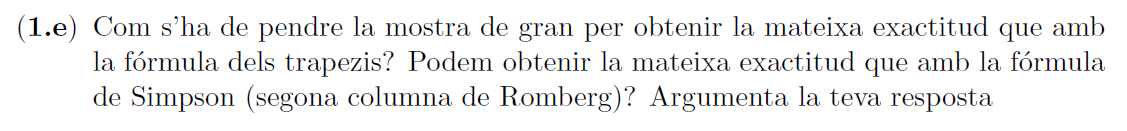

**Resposta:**

function mctab = montecarlo(f,nMAX)
    if nMAX <2
        error('la simulació ha de ser 10^k però k>2')
    end
    a=0; b=1;
    mctab = zeros(nMAX-2,4);
    VE = integral(f,a,b);
    for k=3:nMAX
        M = 10^k;
        x=a+(b-a)*rand(M,1);
        va = sum(f(x))/M;
        mctab(k-2,:)=[k M va abs(va-VE)];
    end
end